# 学習用の動画を生成

このスクリプトの実行方法がわからない方は, [こちらの説明](matlab:open('how_to_use_livescript_jp.mlx'))をお読みください.

## 初期化

clear; close all; clc;
show_message("genCourseTraj_jp",1);

本ワークショップはライブスクリプトの各セクションを順番に実行しながら進めていきます. 
MATLAB初心者の方は, 「このセクションではMATLABで何をしようとしているのか」を理解しながら進めていきましょう. 
(MATLABの使い方に不安がある方は「<a href="https://matlabacademy.mathworks.com/jp/details/matlab-onramp/gettingstarted">MATLAB入門</a>」もおすすめです！). 
MATLAB上級者の方は, スクリプトを読みながらどんどん進めていきましょう. 最後におまけのライブスクリプトも用意しています！

## コースと軌道の生成

### 色の設定

RGBで0から255の値で設定する。

grassColor = [0,193,47]; % 芝生
roadColor = [128,128,128]; % 道路
centerLineColor = [255,255,255]; % 中央線
boundaryLineColor = [255,255,0]; % コースと芝生の境界の線
show_message("genCourseTraj_jp",2);

まずは, 深層学習で使用する画像を作成するために, ロボットが走行する仮想環境を再現します. 
このセクションでは, 仮想環境の色を定義しています. 
それでは, 次のセクションで実際に仮想環境を見てみましょう！

### 周回コースを描画

sizeMap = [400,565]; % 地図の解像度
centerMap = sizeMap([2,1])/2; % 中心
r = 150; % センターの線の半径
im = uint8(repmat(permute(grassColor,[1 3 2]),sizeMap));
im = insertShape(im,"FilledCircle",[10 10 5],"Color","red");
im = insertShape(im,"FilledCircle",[centerMap 180],...
    "Color",roadColor,"Opacity",1);
im = insertShape(im,"Circle",[centerMap 180],...
    "Color",boundaryLineColor,"Opacity",1,"LineWidth",5);
im = insertShape(im,"Circle",[centerMap r],...
    "Color",centerLineColor,"Opacity",1,"LineWidth",5);
im = insertShape(im,"FilledCircle",[centerMap 120],...
    "Color",roadColor,"Opacity",1);
im = insertShape(im,"FilledCircle",[centerMap 120],...
    "Color",grassColor,"Opacity",1,"LineWidth",5);
im = insertShape(im,"Circle",[centerMap 120],...
    "Color",boundaryLineColor,"Opacity",1,"LineWidth",5);
figure;
imshow(im);
proj = currentProject; rootfolder = proj.RootFolder;
imwrite(im,fullfile(rootfolder,'scene','texture','course.png')); % 画像として書き出す
show_message("genCourseTraj_jp",3);

### 軌道の生成

% 地図の実寸
sizeMapReal = [1,1.4143];

% サンプリング周波数
fs = 0.1;

% シミュレーション停止時刻
Tf = 2;

% 時刻のベクトル
time = (0:fs:Tf)';

% 停止時刻で1周するように周波数を規定
f = 1/Tf;

% 円周コース上の位置を角度で指定
angles = 2*pi*f*time;

% 車両座標
trajXY = sizeMapReal(1)/sizeMap(1)*r*[cos(angles) sin(angles)];

% 車両進行方向をX軸としたときのワールド座標系との角度(円の接線方向になるため +90度)
trajTheta = angles + pi/2;

% 時系列のデータに変換 (Simulinkで扱うため)
tsXY = timeseries(trajXY,time,'Name','XY (m)');
tsTheta = timeseries(trajTheta,time,'Name','Theta (rad)');

figure;
subplot(2,1,1);
plot(tsXY);
subplot(2,1,2);
plot(tsTheta);
show_message("genCourseTraj_jp",4);

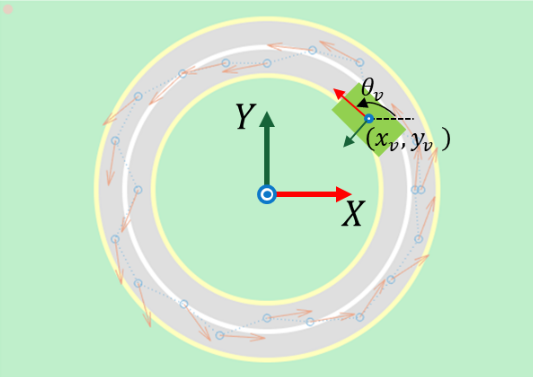

### ランダムに軌道を変化

% 2回目以降でも常に同じ乱数になるようにシードを固定
rng('default');

lenTraj = size(trajXY,1);

% 乱数で車両横方向にランダムに移動
randXYTrain = 0.05*(rand(lenTraj,1)-0.5)*2.*[cos(angles) sin(angles)];
trajXYTrain = trajXY + randXYTrain;

% 乱数で車両向きをランダムに変更
randThetaTrain = pi/8*(rand(lenTraj,1)-0.5)*2;
trajThetaTrain = trajTheta+randThetaTrain;

figure;
imshow(im,'XData',[-1.4143/2 1.4143/2],'YData',[-0.5 0.5]);
alpha 0.5;
hold on;
plot(trajXYTrain(:,1),-trajXYTrain(:,2),'o:');
quiver(trajXYTrain(:,1),-trajXYTrain(:,2),...
    cos(trajThetaTrain),-sin(trajThetaTrain),0.5);

% 時系列のデータに変換
tsXYTrain = timeseries(trajXYTrain,time,'Name','XY (m)');
tsThetaTrain = timeseries(trajThetaTrain,time,'Name','Theta (rad)');

figure;
subplot(2,1,1);
plot(tsXYTrain);
subplot(2,1,2);
plot(tsThetaTrain);
show_message("genCourseTraj_jp",5);

### 保存

% 軌道を念のため保存
save('trainTrajectory.mat','tsXYTrain','tsThetaTrain');

## 3D環境で学習用の動画を生成する

生成した位置や姿勢でカメラ画像をシミュレーションするモデルを開く

open_system('dataset_generator');

シミュレーションを実行(緑の再生ボタンをクリック)し、学習用の動画(`robotTrain.avi`)を生成

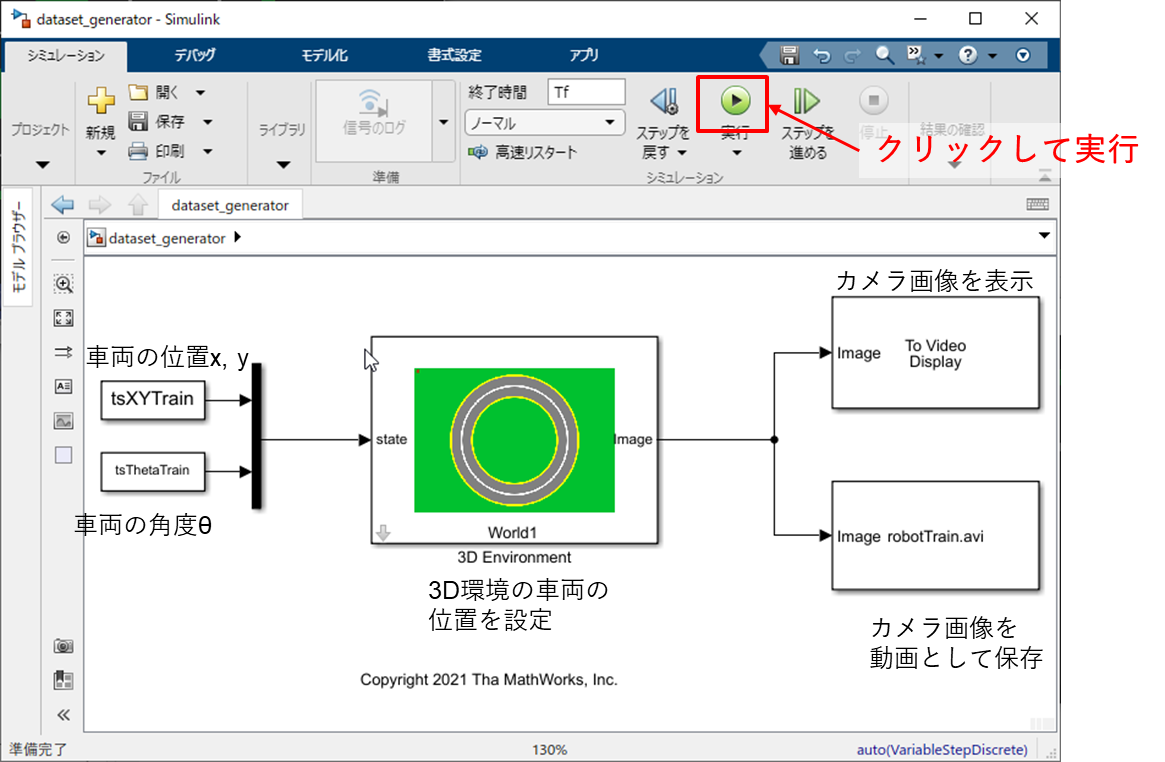

## 次のステップ

[annotateVideo_jp.mlx](matlab:open('annotateVideo_jp.mlx')) で動画のアノテーションを行う

## [メニューに戻る](matlab:open('workshopMenu_jp.mlx'))

*Copyright 2020 The MathWorks, Inc.*